PROBLEM 6 ON HW 3

(a)

close all;
stat = readtable("UCLA_EE_grad_2030.csv");

x = [ones(1, size(stat, 1)); stat{:,1:2}'];
y = (stat{:,3} + 1) / 2;
w = zeros(3, 1);

marks = [5, 100, 500, 1000, 5000, 10000];

figure(1);
hold on;

GPA = stat{:,1};
GRE = stat{:,2};
scatter(GPA(y == 0), GRE(y == 0), 'blue');
scatter(GPA(y == 1), GRE(y == 1), 'red');
x1 = (0:0.1:4);

for iters = 1:10000
    hw = 1 ./ (1 + exp(-(w' * x)));
    del = sum((hw - y') .* x, 2);
    w = w - 0.01 * del;
    
    if any(marks(:) == iters)
        x2 = (-w(1) - x1 * w(2)) / w(3);
        plot(x1, x2);
        fprintf("Iteration %d:\n", iters);
        fprintf("    Weights: [%.4f %.4f %.4f]\n", w');
        J = -sum(y' .* log(hw) + (1 - y)' .* log(1 - hw));
        fprintf("    Loss J(w): %.4f\n", J);
        errors = 0;
        for point = 1:100
            if w' * x(:, point) * (y(point) * 2 - 1) < 0
                errors = errors + 1;
            end
        end
        fprintf("    Accuracy: %d%%\n", 100 - errors);
    end
end

Iteration 5:


    Weights: [-0.6077 -0.1788 -0.4186]


    Loss J(w): 62.1028


    Accuracy: 79%


Iteration 100:


    Weights: [-5.0591 1.2546 0.5597]


    Loss J(w): 31.5298


    Accuracy: 89%


Iteration 500:


    Weights: [-9.6026 2.1187 1.2261]


    Loss J(w): 23.3780


    Accuracy: 90%


Iteration 1000:


    Weights: [-11.2396 2.4857 1.4577]


    Loss J(w): 22.7539


    Accuracy: 90%


Iteration 5000:


    Weights: [-12.5365 2.7815 1.6341]


    Loss J(w): 22.6232


    Accuracy: 90%


Iteration 10000:


    Weights: [-12.5426 2.7829 1.6349]


    Loss J(w): 22.6232


    Accuracy: 90%


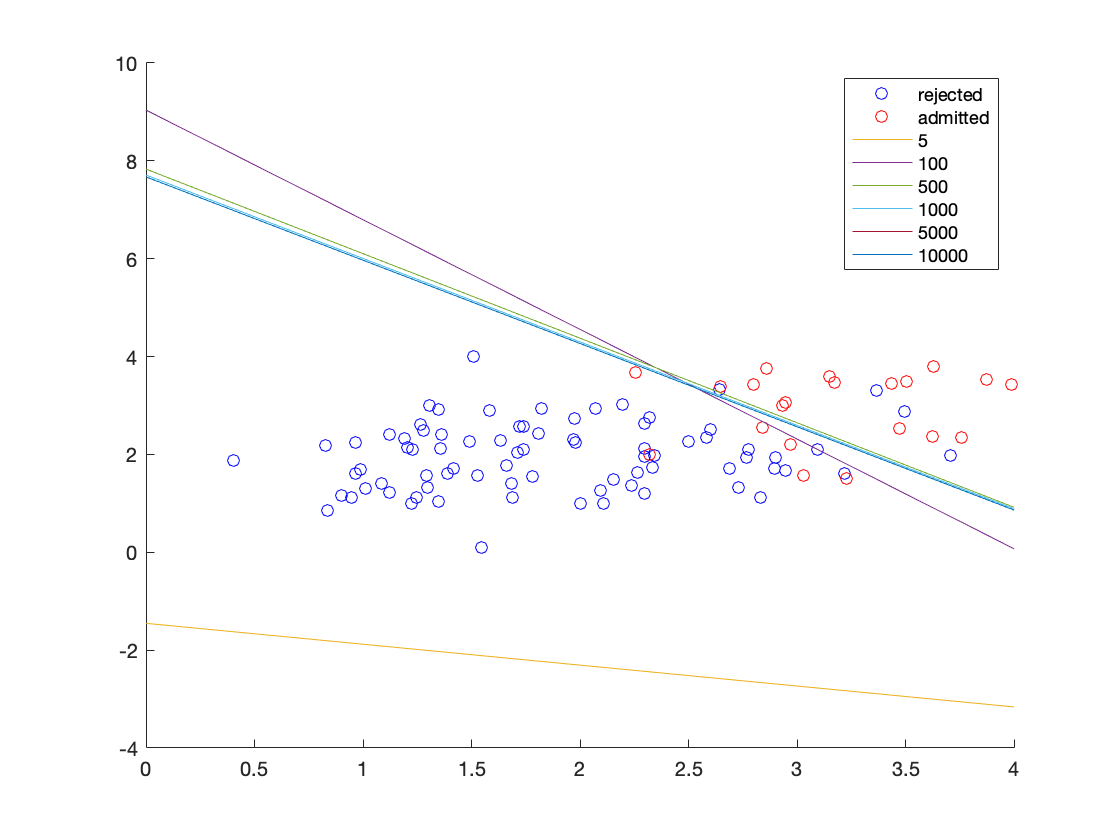


legend('rejected', 'admitted', '5', '100', '500', '1000', '5000', '10000');


stat = readtable("UCLA_EE_grad_2031.csv");

x = [ones(1, size(stat, 1)); stat{:,1:2}'];
y = (stat{:,3} + 1) / 2;
w = zeros(3, 1);

marks = [5, 100, 500, 1000, 5000, 10000];

figure(2);
hold on;

GPA = stat{:,1};
GRE = stat{:,2};
scatter(GPA(y == 0), GRE(y == 0), 'blue');
scatter(GPA(y == 1), GRE(y == 1), 'red');
x1 = (0:0.1:4);

for iters = 1:10000
    hw = 1 ./ (1 + exp(-(w' * x)));
    del = sum((hw - y') .* x, 2);
    w = w - 0.01 * del;
    
    if any(marks(:) == iters)
        x2 = (-w(1) - x1 * w(2)) / w(3);
        plot(x1, x2);
        fprintf("Iteration %d:\n", iters);
        fprintf("    Weights: [%.4f %.4f %.4f]\n", w');
        J = -sum(y' .* log(hw) + (1 - y)' .* log(1 - hw));
        fprintf("    Loss J(w): %.4f\n", J);
        errors = 0;
        for point = 1:100
            if w' * x(:, point) * (y(point) * 2 - 1) < 0
                errors = errors + 1;
            end
        end
        fprintf("    Accuracy: %d%%\n", 100 - errors);
    end
end

Iteration 5:


    Weights: [-0.6147 -0.0596 -0.2684]


    Loss J(w): 52.5866


    Accuracy: 84%


Iteration 100:


    Weights: [-5.6729 1.1863 0.5815]


    Loss J(w): 18.4853


    Accuracy: 98%


Iteration 500:


    Weights: [-11.8075 2.4381 1.5066]


    Loss J(w): 7.0009


    Accuracy: 100%


Iteration 1000:


    Weights: [-15.1482 3.1011 1.9950]


    Loss J(w): 4.5682


    Accuracy: 100%


Iteration 5000:


    Weights: [-25.0273 5.0049 3.4495]


    Loss J(w): 1.6140


    Accuracy: 100%


Iteration 10000:


    Weights: [-30.3694 6.0317 4.2228]


    Loss J(w): 0.9940


    Accuracy: 100%


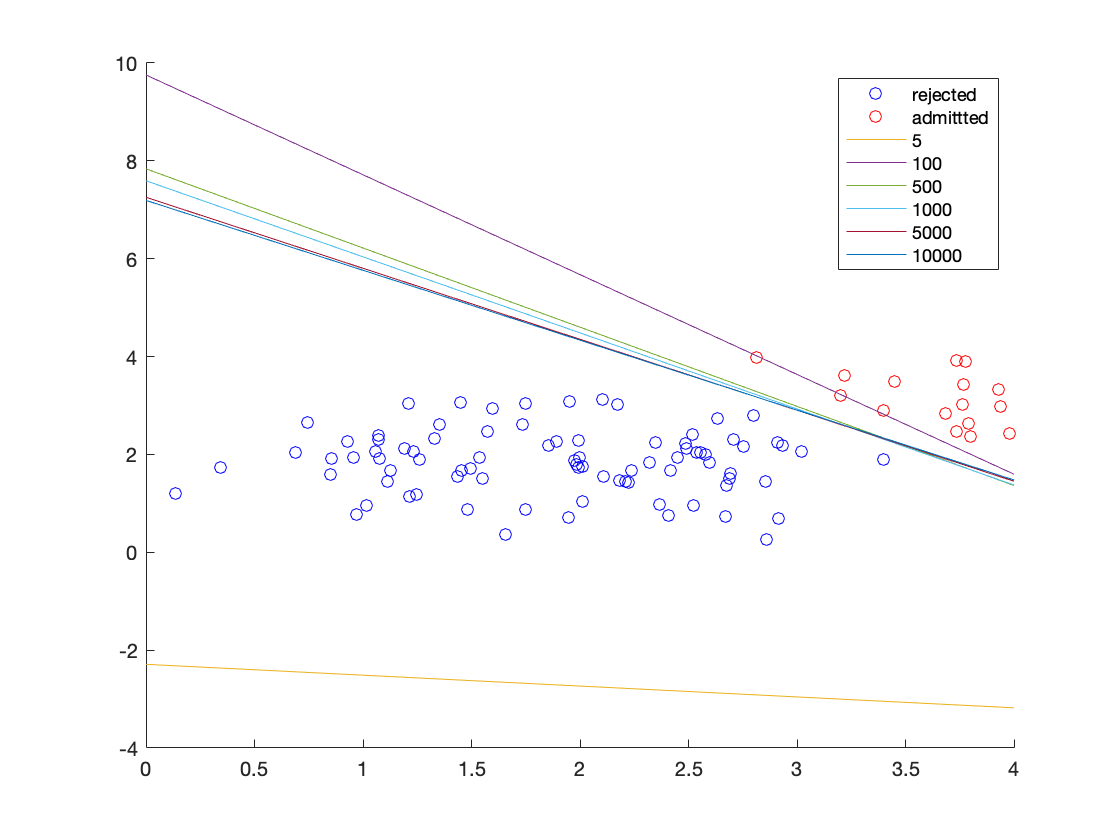


legend('rejected', 'admittted', '5', '100', '500', '1000', '5000', '10000');

(b) The linearly non-separable dataset, aka the first graph (graduation class of 2030) converges in the sense that the loss function barely decreases anymore. However, the accuracy is still not perfect, at 90%. The line also barely changes after 10000 iterations

tldr; if we were to run this algorithm until the data was perfectly separable, the algorithm would never converge. however, the value of loss function does seem to converge.

(c) On the other hand, the other graph (graduation class of 2031) aka the linearly separable dataset, seems to not converge with regards to loss function. It i still decreasing even after 10000 iterations. However, the accuracy with regards to testing data is 100%, and will not change from there. The line also is barely changing positions now. I tried running the second dataset with 1000000 iterations ( 1 million ), and the loss function reached all the way down to 0.0203!!. It will just keep decreasing, as a better and better fit for the data will be the perfect minimal value of the loss function even though accuracy is stilll 100% through all of this. There is an empty space in between the lineraly separable data where the point can lie anywhere, and at this point the line is just perfecting its placement.

tldr; if we were to run this algorithm until the data was perfectly separable, the algorithm would converge in under 500 iterations. however, the value of the loss function does not seem to converge even after 1 million iterations.